
8793

ans = 8793

IAE = 31907.5169				P = 254.8583		I = 732.3912		D = 22.1647
IAE = 16430.6554				P = 169.9434		I = 263.1156		D = 19.1688
IAE = 27294.9479				P = 193.7411		I = 720.8429		D = 36.8219
IAE = 22984.1108				P = 54.3217		I = 455.7415		D = 50.6063
IAE = 22877.3065				P = 221.276		I = 132.1647		D = 53.0007
IAE = 7215.6737				P = 49.4352		I = 821.1171		D = 4.1345
IAE = 14317.7798				P = 124.5024		I = 88.3964		D = 31.8507
IAE = 17969.1109				P = 167.8264		I = 76.7454		D = 9.2647
IAE = 21269.0983				P = 59.384		I = 447.0828		D = 31.4276
IAE = 2916.7628				P = 123.8957		I = 561.7407		D = 1.6528
IAE = 22035.9239				P = 188.4698		I = 702.6575		D = 43.9422
IAE = 19283.0816				P = 198.5451		I = 828.2803		D = 52.1506
IAE = 17627.3406				P = 48.7339		I = 653.2602		D = 23.0276
IAE = 19634.8041				P = 83.4463		I = 116.3586		D = 58.1043
IAE = 6534.7344				P = 24.5971		I = 662.4735		D = 6.3709
IAE = 26077.4467				P = 33.1515		I = 57.5065		D = 18.3296
IAE = 22436.7234				P = 175.5361		I = 366.7857		D = 46.6778

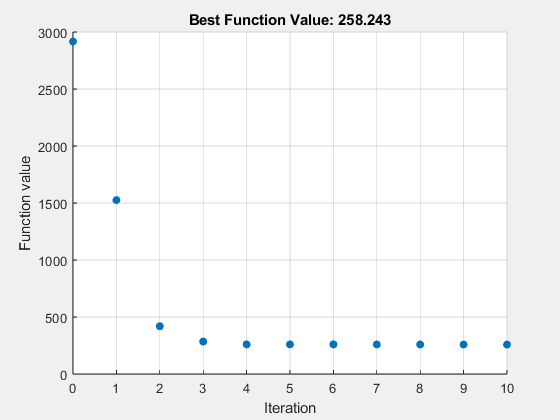

% Set nondefault solver options
options2 = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    10,"MaxStallIterations",5,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options2);


% Clear variables
clearvars options2